## Evaluation script for a trained DQN agent

#### This script loads a previously trained RL agent and evaluates it in the environment. It shows the agent's performance in several test episodes.

clc;
clear all;
close all;

### Environment Configuration and Data Loading

fprintf('Loading parameters and defining the environment...\n');

Loading parameters and defining the environment...


%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('code');

Adding matlab path to: D:\code\SIM\code


% Load the same base parameters as in training
Parameters; % Script containing necessary variables

total_iteration = 1

Wireless packet type: SC


N_y = 4

M_x = 15

M_y = 15

zeta =     0.9800    0.9810    0.9820    0.9830    0.9840    0.9850    0.9860    0.9870    0.9880    0.9890    0.9900    0.9910    0.9920    0.9930    0.9940    0.9950    0.9960    0.9970    0.9980    0.9990


T_coh = 0.0021

N_packets_coh = 9

T = 144

SNR_dB = 11.6443


% Load trained agent
try
    % path_enhanced = fullfile('..', 'Dataset', 'dqn_agent_random_Reward_C.mat');
    path_enhanced = fullfile('..', 'Dataset', 'dqn_agent_navigation_144_steps_per_epsiode.mat');
    load(path_enhanced, 'agent','criticNet');
    fprintf('Trained agent successfully loaded.\n\n');
catch
    error('The agent file "dqn_agent_random_Reward_B.mat" could not be found. Make sure it is in the same folder.');
end

Trained agent successfully loaded.



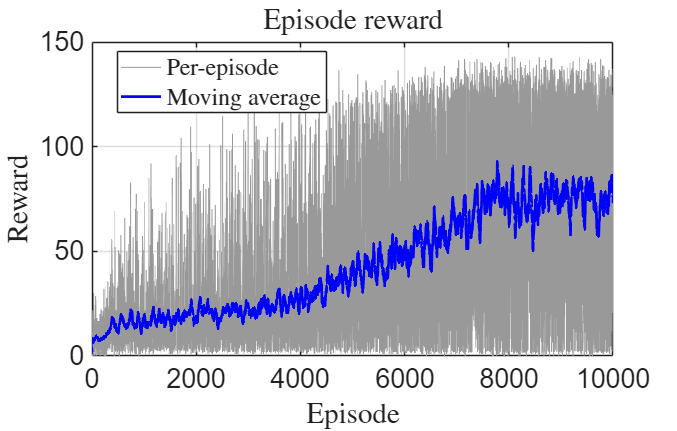


S = load(path_enhanced, 'trainingStats');
trainingStats = S.trainingStats;

% Pull the relevant series, defending against missing fields
epIdx       = trainingStats.EpisodeIndex(:);
epReward    = trainingStats.EpisodeReward(:);
epAvgReward = trainingStats.AverageReward(:);
epSteps     = trainingStats.EpisodeSteps(:);

if isfield(trainingStats,'TotalAgentSteps') && ~isempty(trainingStats.TotalAgentSteps)
    totalAgentSteps = trainingStats.TotalAgentSteps(:);
else
    % Fallback: cumulative episode lengths
    totalAgentSteps = cumsum(epSteps);
end

if isfield(trainingStats,'EpisodeQ0') && ~isempty(trainingStats.EpisodeQ0)
    epQ0 = trainingStats.EpisodeQ0(:);
    haveQ0 = true;
else
    epQ0 = nan(size(epIdx));
    haveQ0 = false;
end

%% Figure 1 — training quality vs episode
figure('Name','Training quality (per episode)','Position',[100 100 1100 700]);

plot(epIdx, epReward,    'Color',[0.6 0.6 0.6], 'LineWidth',0.8); hold on;
plot(epIdx, epAvgReward, 'b-',  'LineWidth',2);
xlabel('Episode','Interpreter','latex');
ylabel('Reward','Interpreter','latex');
title('Episode reward','Interpreter','latex');
legend({'Per-episode','Moving average'},'Location','best','Interpreter','latex');
grid on; set(gca,'FontSize',font);



%% Numerical summary
nEp = numel(epReward);
[bestR, bestEp] = max(epReward);
fprintf('\n=== Training summary ===\n');


=== Training summary ===


fprintf('Episodes completed   : %d\n', nEp);

Episodes completed   : 10000


fprintf('Total agent steps    : %d\n', totalAgentSteps(end));

Total agent steps    : 614215


fprintf('Final episode reward : %.3f\n', epReward(end));

Final episode reward : 2.082


fprintf('Final avg reward     : %.3f\n', epAvgReward(end));

Final avg reward     : 72.989


fprintf('Best episode reward  : %.3f (episode %d)\n', bestR, bestEp);

Best episode reward  : 143.028 (episode 8116)


fprintf('Mean steps/episode   : %.1f\n', mean(epSteps));

Mean steps/episode   : 61.4


fprintf('========================\n\n');


% After training, extract the critic (Q-network) from the agent
critic = getCritic(agent);

%% Q-function bar plot for a specific DOA
psi_x_test = 2*pi * 0.6;
psi_y_test = 2*pi * 0.3;

a_psi_x   = exp(1i * psi_x_test * ((1:EnvPars.N_x)-1))';
a_psi_y   = exp(1i * psi_y_test * ((1:EnvPars.N_y)-1))';
a_psi_x_y = kron(a_psi_y, a_psi_x);

% Query Q-network once per (t_x, t_y) position — must include position in obs
Q_map_pos = zeros(EnvPars.T_x, EnvPars.T_y);   % Q-value at best action per position

for t_psi = 1:EnvPars.T
    tx  = EnvPars.t_x(t_psi);
    ty  = EnvPars.t_y(t_psi);
    v0  = EnvPars.U_func(1:EnvPars.N, t_psi);
    r   = sqrt(db2pow(EnvPars.SNR_dB)) * EnvPars.G * diag(v0') * a_psi_x_y;

    % ← observation now includes position — matches training spec
    obs   = [abs(r).^2; tx; ty];              % (N+2) × 1
    Q_all = getValue(critic, {obs});           % 1 × n_actions (9 values)
    Q_map_pos(tx, ty) = max(Q_all);           % best Q at this position
end

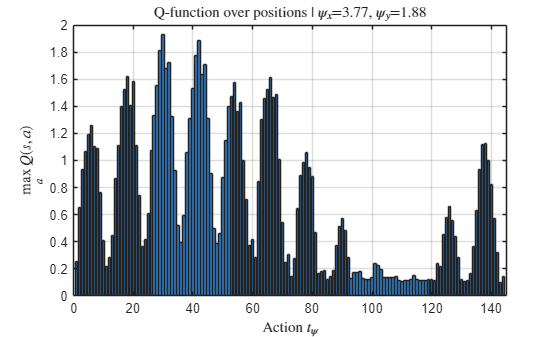


% Bar plot — Q-value across all 144 (t_x,t_y) positions
figure;
bar(1:EnvPars.T, Q_map_pos(:), 'FaceColor', [0.2 0.5 0.8]);
xlabel('Action $t_\psi$', 'Interpreter', 'latex');
ylabel('$\max_a Q(s, a)$', 'Interpreter', 'latex');
title(sprintf('Q-function over positions | $\\psi_x$=%.2f, $\\psi_y$=%.2f', ...
              psi_x_test, psi_y_test), 'Interpreter', 'latex');
grid on;

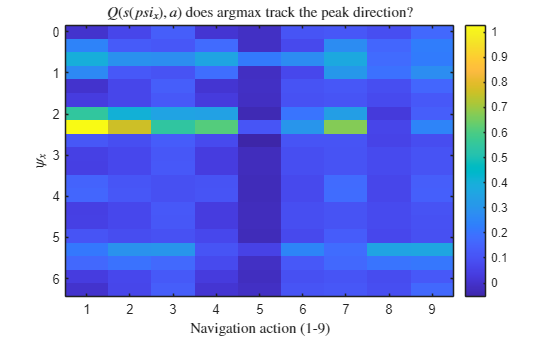


%% Q heatmap over (psi_x, t_curr_position)
N_test    = 20;
psi_x_vec = linspace(0, 2*pi, N_test);

% Fix starting position at centre of grid for the sweep
tx_fixed  = round(EnvPars.T_x / 2);
ty_fixed  = round(EnvPars.T_y / 2);

Q_map = zeros(N_test, EnvPars.n_actions);   % n_actions=9, not T

for i = 1:N_test
    a_x   = exp(1i * psi_x_vec(i) * ((1:EnvPars.N_x)-1))';
    a_y   = exp(1i * pi            * ((1:EnvPars.N_y)-1))';
    t_psi = (ty_fixed - 1) * EnvPars.T_x + tx_fixed;
    v0    = EnvPars.U_func(1:EnvPars.N, t_psi);
    r     = sqrt(db2pow(EnvPars.SNR_dB)) * EnvPars.G * diag(v0') * kron(a_y, a_x);

    % ← position appended
    obs        = [abs(r).^2; tx_fixed; ty_fixed];   % (N+2) × 1
    Q_map(i,:) = getValue(critic, {obs});            % 1 × 9
end

figure;
imagesc(1:EnvPars.n_actions, psi_x_vec, Q_map);
colorbar;
xlabel('Navigation action (1-9)', 'Interpreter', 'latex');
ylabel('$\psi_x$',               'Interpreter', 'latex');
title('$Q(s(psi_x), a)$  does argmax track the peak direction?', ...
      'Interpreter', 'latex');

#### Theoretical evaluation of the Q function

%% Theoretical Q★ via Dynamic Programming (Value Iteration)
% State space:  (pos_idx, t_x, t_y) — calibration position + grid location
% Action space: 9 relative moves from EnvPars.delta_moves
% Reward:       peak_map(pos, t_x, t_y) / global_max(pos)

Calibration

=== Calibration phase ===
Grid: 10 x 5 = 50 calibration positions
Calibration complete.




fprintf('=== Value Iteration for Q★ ===\n');

=== Value Iteration for Q★ ===



%% Parameters
gamma     = 0.5;
tol_conv  = 1e-6;
max_iter  = 1000;
n_a       = EnvPars.n_actions;   % 9
T_x       = EnvPars.T_x;         % 12
T_y       = EnvPars.T_y;         % 12
N_cal     = EnvPars.N_cal;

%% Precompute normalised reward for every (pos, t_x, t_y)
% R(pos, tx, ty) = peak_map(pos, tx, ty) / global_max(pos)
R_map = zeros(N_cal, T_x, T_y);
for pos = 1:N_cal
    % R_map(pos,:,:) = (squeeze(peak_map(pos,:,:)) / EnvPars.global_max_cal(pos)).^2;   % normalised ∈ (0,1]
    threshold = 0.8;   % only positions with >80% of peak get positive reward
    slice     = squeeze(peak_map(pos,:,:)) / EnvPars.global_max_cal(pos);
    R_map(pos,:,:) = max(0, (slice - threshold) / (1 - threshold));
end

%% Value function V★(pos, t_x, t_y) — initialise to zero
V     = zeros(N_cal, T_x, T_y);
V_new = zeros(N_cal, T_x, T_y);

%% Value Iteration
for iter = 1:max_iter
    V_old = V;

    for pos = 1:N_cal
        for tx = 1:T_x
            for ty = 1:T_y

                % Immediate reward at current position
                r_now = R_map(pos, tx, ty);

                % Evaluate all 9 actions — find max future value
                Q_vals = zeros(n_a, 1);
                for a = 1:n_a
                    % Next position — wrap around grid edges
                    tx_next = mod(tx - 1 + EnvPars.delta_moves(a,1), T_x) + 1;
                    ty_next = mod(ty - 1 + EnvPars.delta_moves(a,2), T_y) + 1;

                    % Bellman equation
                    Q_vals(a) = r_now + gamma * V(pos, tx_next, ty_next);
                end

                V_new(pos, tx, ty) = max(Q_vals);
            end
        end
    end

    V = V_new;

    % Check convergence
    delta_V = max(abs(V(:) - V_old(:)));
    if mod(iter, 50) == 0
        fprintf('  Iteration %d | max ΔV = %.2e\n', iter, delta_V);
    end
    if delta_V < tol_conv
        fprintf('Converged at iteration %d | max ΔV = %.2e\n', iter, delta_V);
        break;
    end
end

Converged at iteration 21 | max ΔV = 9.54e-07



%% Extract Q★ and optimal policy π★ from converged V
% Q★(pos, tx, ty, a) = R(pos,tx,ty) + γ * V★(pos, tx_next, ty_next)
Q_star = zeros(N_cal, T_x, T_y, n_a);
policy = zeros(N_cal, T_x, T_y);   % optimal action index (1–9)

for pos = 1:N_cal
    for tx = 1:T_x
        for ty = 1:T_y
            r_now  = R_map(pos, tx, ty);
            Q_vals = zeros(n_a, 1);

            for a = 1:n_a
                tx_next  = mod(tx - 1 + EnvPars.delta_moves(a,1), T_x) + 1;
                ty_next  = mod(ty - 1 + EnvPars.delta_moves(a,2), T_y) + 1;
                Q_vals(a) = r_now + gamma * V(pos, tx_next, ty_next);
            end

            [~, policy(pos, tx, ty)] = max(Q_vals);
            Q_star(pos, tx, ty, :)   = Q_vals;
        end
    end
end

fprintf('Q★ and π★ computed for all %d positions.\n\n', N_cal);

Q★ and π★ computed for all 50 positions.



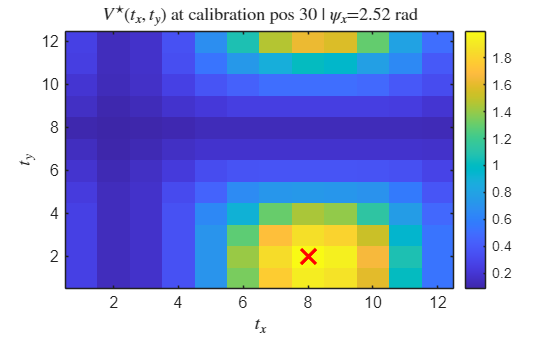


%% ── PLOTS ────────────────────────────────────────────────────────────────

%% Plot 1 — V★ landscape for one calibration position
pos_probe = round(N_cal * 0.6);   % pick a representative position
figure;
imagesc(1:T_x, 1:T_y, squeeze(V(pos_probe,:,:))');
colorbar; axis xy;
hold on;
plot(EnvPars.best_tx_cal(pos_probe), EnvPars.best_ty_cal(pos_probe), ...
     'rx', 'MarkerSize', 16, 'LineWidth', 2.5);
xlabel('$t_x$', 'Interpreter','latex');
ylabel('$t_y$', 'Interpreter','latex');
title(sprintf('$V^\\star(t_x,t_y)$ at calibration pos %d | $\\psi_x$=%.2f rad', ...
              pos_probe, EnvPars.psi_x_cal(pos_probe)), 'Interpreter','latex');
set(gca,'FontSize',12);

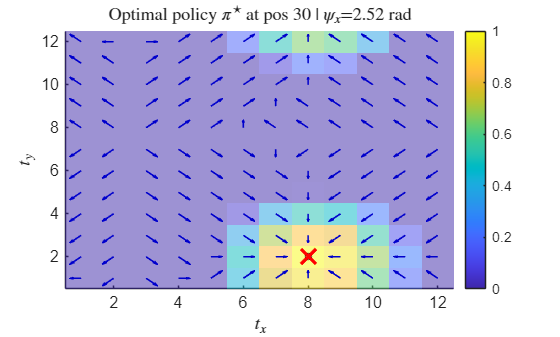


%% Plot 2 — Optimal policy arrow map for same position
figure; hold on;
imagesc(1:T_x, 1:T_y, squeeze(R_map(pos_probe,:,:))');
alpha(0.5); axis xy; colorbar;

for tx = 1:T_x
    for ty = 1:T_y
        a  = policy(pos_probe, tx, ty);
        dx = EnvPars.delta_moves(a, 1);
        dy = EnvPars.delta_moves(a, 2);
        if dx == 0 && dy == 0
            plot(tx, ty, 'ko', 'MarkerSize', 5);   % stay action
        else
            quiver(tx, ty, dx*0.35, dy*0.35, 0, ...
                   'Color', [0 0 0.8], 'LineWidth', 1.2, 'MaxHeadSize', 1.5);
        end
    end
end
plot(EnvPars.best_tx_cal(pos_probe), EnvPars.best_ty_cal(pos_probe), ...
     'rx', 'MarkerSize', 16, 'LineWidth', 2.5);
xlim([0.5, T_x+0.5]); ylim([0.5, T_y+0.5]);
xlabel('$t_x$', 'Interpreter','latex');
ylabel('$t_y$', 'Interpreter','latex');
title(sprintf('Optimal policy $\\pi^\\star$ at pos %d | $\\psi_x$=%.2f rad', ...
              pos_probe, EnvPars.psi_x_cal(pos_probe)), 'Interpreter','latex');
set(gca,'FontSize',12);

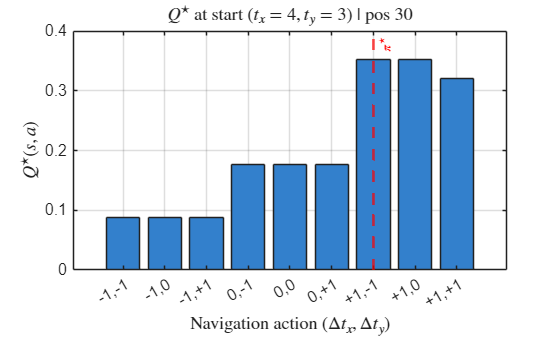



%% Plot 3 — Q★ over the 9 actions at the starting position
% Shows which action has the highest Q-value before any move
tx_start = randi(T_x);
ty_start = randi(T_y);
Q_at_start = squeeze(Q_star(pos_probe, tx_start, ty_start, :));

action_labels = {'-1,-1'; '-1,0'; '-1,+1'; '0,-1'; '0,0'; '0,+1'; '+1,-1'; '+1,0'; '+1,+1'};
figure;
bar(1:n_a, Q_at_start, 'FaceColor', [0.2 0.5 0.8]);
xticks(1:n_a);
xticklabels(action_labels);
xlabel('Navigation action $(\Delta t_x, \Delta t_y)$', 'Interpreter','latex');
ylabel('$Q^\star(s, a)$',                               'Interpreter','latex');
title(sprintf('$Q^\\star$ at start $(t_x=%d, t_y=%d)$ | pos %d', ...
              tx_start, ty_start, pos_probe), 'Interpreter','latex');
[~, best_a] = max(Q_at_start);
xline(best_a, 'r--', 'LineWidth', 2, 'Label', '$\pi^\star$', ...
      'Interpreter', 'latex');
grid on; set(gca,'FontSize',12);

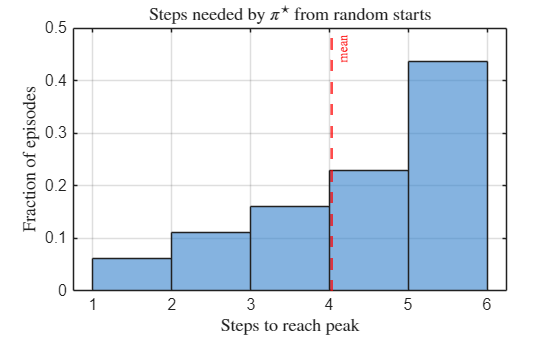


%% Plot 4 — Simulate optimal policy from random starts, measure steps to peak
N_sim         = 100;
steps_to_peak = zeros(N_cal, N_sim);

for pos = 1:N_cal
    for sim = 1:N_sim
        tx = randi(T_x);
        ty = randi(T_y);

        for k = 1:EnvPars.MaxStepsPerEpisode
            a       = policy(pos, tx, ty);
            tx_next = mod(tx - 1 + EnvPars.delta_moves(a,1), T_x) + 1;
            ty_next = mod(ty - 1 + EnvPars.delta_moves(a,2), T_y) + 1;

            if tx_next == EnvPars.best_tx_cal(pos) && ...
               ty_next == EnvPars.best_ty_cal(pos)
                steps_to_peak(pos, sim) = k;
                break;
            end
            tx = tx_next;
            ty = ty_next;
        end
    end
end

figure;
histogram(steps_to_peak(steps_to_peak > 0), ...
          'BinWidth', 1, 'FaceColor', [0.2 0.5 0.8], 'Normalization','probability');
xlabel('Steps to reach peak',    'Interpreter','latex');
ylabel('Fraction of episodes',   'Interpreter','latex');
title('Steps needed by $\pi^\star$ from random starts', 'Interpreter','latex');
xline(mean(steps_to_peak(steps_to_peak>0)), 'r--', 'LineWidth', 2, ...
      'Label', 'mean', 'Interpreter','latex');
grid on; set(gca,'FontSize',12);


%% Summary
reached     = steps_to_peak(steps_to_peak > 0);
not_reached = sum(steps_to_peak(:) == 0);
fprintf('=== Optimal policy simulation (%d starts × %d positions) ===\n', N_sim, N_cal);

=== Optimal policy simulation (100 starts × 50 positions) ===


fprintf('Mean steps to peak   : %.2f\n',  mean(reached));

Mean steps to peak   : 4.03


fprintf('Max  steps to peak   : %d\n',    max(reached));

Max  steps to peak   : 6


fprintf('Never reached peak   : %.1f%%\n', 100*not_reached/(N_cal*N_sim));

Never reached peak   : 0.0%


fprintf('Within MaxSteps (%d) : %.1f%%\n', EnvPars.MaxStepsPerEpisode, ...
        100*mean(reached <= EnvPars.MaxStepsPerEpisode));

Within MaxSteps (144) : 100.0%


fprintf('=========================================================\n');

### Evaluation for a given number of steps

% Parameters
t = 0:delta_time:time_simul;     % time vector in s

EnvPars.tolerance = pi/25;
%% Initialization
Nsteps = length(t);
pos_MU_traj = zeros(3, Nsteps);

% Initial position
current_pos = pos_MU_init(:);
current_pos(1) = min(max(current_pos(1), 0), L_hall);
current_pos(2) = min(max(current_pos(2), 0), W_hall);

pos_MU_traj(:,1) = current_pos;

% Initial mobility state
state = "move";   % either "move" or "pause"

% First target waypoint
target_pos = [L_hall*rand; W_hall*rand; current_pos(3)];

% Pause handling
pause_end_time = -inf;

%% Time evolution
for k = 2:Nsteps
    
    dt = t(k) - t(k-1);
    
    % In case of non-positive time step, keep previous position
    if dt <= 0
        pos_MU_traj(:,k) = pos_MU_traj(:,k-1);
        continue;
    end
    
    if state == "move"
        
        % Vector toward target
        dvec = target_pos(1:2) - current_pos(1:2);
        dist_to_target = norm(dvec);
        travel_dist = MU_speed * dt;
        
        if dist_to_target <= travel_dist
            % Reach waypoint within this time step
            current_pos(1:2) = target_pos(1:2);
            
            % Switch to pause state
            pause_duration = pause_min + (pause_max - pause_min)*rand;
            pause_end_time = t(k) + pause_duration;
            state = "pause";
            
        else
            % Move toward waypoint
            direction = dvec / dist_to_target;
            current_pos(1:2) = current_pos(1:2) + direction * travel_dist;
        end
        
    elseif state == "pause"
        
        % Stay still during pause
        if t(k) >= pause_end_time
            % Pause finished, choose new waypoint and move again
            target_pos = [L_hall*rand; W_hall*rand; current_pos(3)];
            state = "move";
        end
        
    end
    
    % Store position
    pos_MU_traj(:,k) = current_pos;
end

% Enforce constant z-coordinate
pos_MU_traj(3,:) = pos_MU_init(3);


#### Including the channel coherence time

**Description**:In this block we include the number of transmittions along wich the channel is coherent.This is similar to assuming the user keeps the same position.

% pos_MU_traj = repelem(pos_MU_traj, 1, floor(N_packets_coh*delta_time/T_coh));
pos_MU_traj = repelem(pos_MU_traj, 1, 50);

#### Ploting the mobility of the user

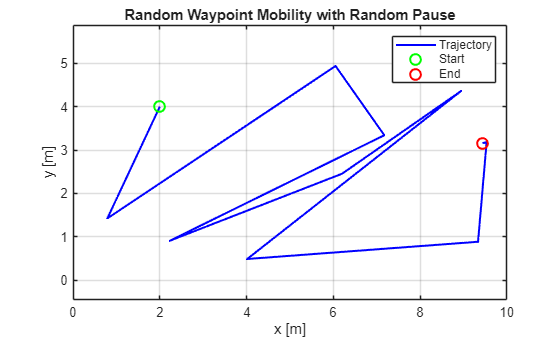

figure;
plot(pos_MU_traj(1,:), pos_MU_traj(2,:), 'b-', 'LineWidth', 1.5); hold on;
plot(pos_MU_traj(1,1), pos_MU_traj(2,1), 'go', 'MarkerSize', 8, 'LineWidth', 1.5);
plot(pos_MU_traj(1,end), pos_MU_traj(2,end), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
xlim([0 L_hall]);
ylim([0 W_hall]);
xlabel('x [m]');
ylabel('y [m]');
title('Random Waypoint Mobility with Random Pause');
grid on;
axis equal;
legend('Trajectory','Start','End');


% %% Animation of the mobile user trajectory
% 
% figure;
% hold on;
% grid on;
% axis equal;
% xlim([0 L_hall]);
% ylim([0 W_hall]);
% xlabel('$x$ [m]','Interpreter','latex');
% ylabel('$y$ [m]','Interpreter','latex');
% title('Mobile User Random Waypoint Trajectory');
% 
% % Draw hall boundary
% rectangle('Position',[0, 0, L_hall, W_hall], 'EdgeColor','k', 'LineWidth',1.5);
% 
% % Plot full trajectory as dashed reference
% plot(pos_MU_traj(1,:), pos_MU_traj(2,:), '--', 'Color', [0.7 0.7 0.7], 'LineWidth', 1);
% 
% % Initialize animated trajectory and current user marker
% h_traj = plot(pos_MU_traj(1,1), pos_MU_traj(2,1), 'b-', 'LineWidth', 2);
% h_user = plot(pos_MU_traj(1,1), pos_MU_traj(2,1), 'ro', ...
%     'MarkerFaceColor','r', 'MarkerSize',8);
% 
% % Optional text showing current time
% h_time = text(L_hall*(1-0.2), 0.91*W_hall, sprintf('$t = %.2f$ [s]', t(1)), ...
%     'FontSize', font, 'Color', 'k','BackgroundColor','w','Interpreter','latex');
% 
% set(gca,'FontSize',font)
% 
% for k = 1:2*N_packets_coh:length(t)
% 
%     % Update traveled path
%     set(h_traj, 'XData', pos_MU_traj(1,1:k), 'YData', pos_MU_traj(2,1:k));
% 
%     % Update current user position
%     set(h_user, 'XData', pos_MU_traj(1,k), 'YData', pos_MU_traj(2,k));
% 
%     % Update time label
%     set(h_time, 'String', sprintf('t = %.2f s', t(k)));
% 
%     drawnow;
% 
%     % Optional real-time pacing
%     if k < length(t)
%         pause((t(k+1) - t(k))/2);
%     end
% end


#### Agent Evaluation

%% Preallocate/collect episode data
actions = [];
rewards = [];
psi_x_est_history = [];
psi_y_est_history = [];
% psi_x_real = [];
% psi_y_real = [];

% Pre-compute electric angle trajectories from position trajectory
psi_x_traj = zeros(Nsteps, 1);%x-coordinate of the electric angles
psi_y_traj = zeros(Nsteps, 1);%y-coordinate of the electric angles
for k = 1:Nsteps
    [psi_x_traj(k), psi_y_traj(k)] = computePsiFromPos(pos_MU_traj(:,k), EnvPars);
end

% Stash trajectory + size in EnvPars so step/reset can see it
EnvPars.psi_x_traj = psi_x_traj;
EnvPars.psi_y_traj = psi_y_traj;
EnvPars.maxSteps   = Nsteps;

% Preallocate logs for one long episode
actions          = zeros(Nsteps, 1);
rewards          = zeros(Nsteps, 1);
psi_x_agent_est_log    = zeros(Nsteps, 1);
psi_y_agent_est_log    = zeros(Nsteps, 1);
psi_x_traj_log   = zeros(Nsteps, 1);%MU psi_x_traj as reed it from the agent
psi_y_traj_log   = zeros(Nsteps, 1);%MU psi_y_traj as reed it from the agent
agent_tx        = zeros(Nsteps, 1);
agent_ty        = zeros(Nsteps, 1);
error_log        = zeros(Nsteps, 1);

% One reset, then one long step loop
[observation, LoggedSignals] = resetFunction_deployment(EnvPars);

% criticNet = getModel(getCritic(agent));  % bare dlnetwork, GPU-independent
% path_critic = fullfile('..', 'Dataset', 'dqn_critic_random_Reward_B.mat');
% save(path_critic, 'agent', 'trainingStats', 'criticNet');


stepCount = 0;
while stepCount < Nsteps-1
    % [action, ~] = getAction(agent, observation);
    obs_dl = dlarray(single(observation(:)), 'CB');   % observation is already 18D
    qVals  = extractdata(predict(criticNet, obs_dl)); % now correctly 18D input
    [~, action] = max(qVals);   % greedy: highest Q-value action
    if iscell(action), action = action{1}; end

    [nextObs, reward, LoggedSignals] = ...
        stepFunction_deployment(action, LoggedSignals, EnvPars);

    stepCount = stepCount + 1;
    actions(stepCount)        = double(action);
    % Inside the while loop, replace these two lines:
    agent_tx(stepCount) = LoggedSignals.t_x;   % recorded by stepFunction
    agent_ty(stepCount) = LoggedSignals.t_y;   % recorded by stepFunction

    rewards(stepCount)        = reward;
    psi_x_agent_est_log(stepCount)  = LoggedSignals.psi_x_est;
    psi_y_agent_est_log(stepCount)  = LoggedSignals.psi_y_est;
    psi_x_traj_log(stepCount) = LoggedSignals.psi_x_traj;
    psi_y_traj_log(stepCount) = LoggedSignals.psi_y_traj;
    error_log(stepCount)      = LoggedSignals.error_sum;

    observation = nextObs;
end

### Brute Force solution

%% Brute-force per-frame: find optimal (t_psi, n_psi) for the current true angle
R_max_per_frame        = zeros(EnvPars.T_x, EnvPars.T_y, Nsteps);
tx_brute_force_per_frame       = zeros(Nsteps, 1);   % 1-indexed in {1,...,T_x}
ty_brute_force_per_frame       = zeros(Nsteps, 1);   % 1-indexed in {1,...,T_y}
psi_nx_brute_force_per_frame  = zeros(Nsteps, 1);   % 1-indexed in {1,...,N_x}
psi_ny_brute_force_per_frame  = zeros(Nsteps, 1);   % 1-indexed in {1,...,N_y}

for k = 1:Nsteps
    a_psi_x_k   = exp(1i * psi_x_traj_log(k) * ((1:EnvPars.N_x) - 1))';
    a_psi_y_k   = exp(1i * psi_y_traj_log(k) * ((1:EnvPars.N_y) - 1))';
    a_psi_x_y_k = kron(a_psi_y_k, a_psi_x_k);
    
    R_array_k = zeros(EnvPars.T_x, EnvPars.T_y);
    idx_psi_n = zeros(EnvPars.T_x, EnvPars.T_y);
    
    %This loop evaluates the values of the 2D-DFT for all combinations of
    %psi_x and psi_y, that is, for all posible angular shifts given by the
    %variable t_psi in the range 1 to T
    for t_psi = 1:EnvPars.T
        tx_loc = EnvPars.t_x(t_psi);   % 1-indexed value
        ty_loc = EnvPars.t_y(t_psi);   % 1-indexed value
        
        v0_loc = EnvPars.U_func(1:EnvPars.N, t_psi);% The U function is defined in Parameters.mlx, accessible at the Parameters folder
        Up_loc = diag(v0_loc');
        r_loc  = sqrt(db2pow(EnvPars.SNR_dB)) * EnvPars.G * Up_loc * a_psi_x_y_k;
        R_loc  = reshape(abs(r_loc), [EnvPars.N_x, EnvPars.N_y]);   % N_x rows, N_y cols
        
        % Store both the peak value AND the location of that peak within R_loc
        [R_array_k(tx_loc, ty_loc), idx_psi_n(tx_loc, ty_loc)] = ...
            max(R_loc, [], 'all');
    end
    
    R_max_per_frame(:,:,k)     = R_array_k;
   
    
    % Find the (tx, ty) that gives the global maximum
    [~, idx_global] = max(R_array_k(:));
    [ty_brute_force_per_frame(k), tx_brute_force_per_frame(k)] = ind2sub(size(R_array_k), idx_global);
    % opt_tx_per_frame, opt_ty_per_frame are 1-indexed in {1,...,T_x}, {1,...,T_y}
    
    % % Look up the (n_psi_x, n_psi_y) at that optimal (tx, ty)
    best_idx_in_R = idx_psi_n(tx_brute_force_per_frame(k), ty_brute_force_per_frame(k));
    [psi_ny_brute_force_per_frame(k), psi_nx_brute_force_per_frame(k)] = ...
        ind2sub([EnvPars.N_x, EnvPars.N_y], best_idx_in_R);
end

%% Convert (n_psi, t_psi) into continuous angles
% Both opt_tx_per_frame and opt_psi_x_n_per_frame are 1-indexed,
% so subtract 1 from each to get the 0-indexed offsets used in the angle formula.
psi_x_brute_force_per_frame = 2*pi * ( ...
    (psi_nx_brute_force_per_frame - 1) + (tx_brute_force_per_frame - 1)/EnvPars.T_x ...
    ) / EnvPars.N_x;
psi_y_brute_force_per_frame = 2*pi * ( ...
    (psi_ny_brute_force_per_frame - 1) + (ty_brute_force_per_frame - 1)/EnvPars.T_y ...
    ) / EnvPars.N_y;


%% Animation: R from true vs. estimated steering vector
% Left  panel: R using a_psi_x_y from the true (psi_x_real, psi_y_real)
% Right panel: R using a_psi_x_y from the estimated (psi_x_est, psi_y_est)
% Both panels use the agent's chosen t_psi at each step.

% Nsteps = numel(psi_x_real_log);

% Pre-compute |R| for both cases at every step
R_brute_force_per_frame  = zeros(EnvPars.N_x, EnvPars.N_y, Nsteps);

% Continuous (non-codebook) phase preset that focuses the SIM at angle (psi_x, psi_y)
makeUpFromAngle = @(psi_x, psi_y) diag(exp(-1i * ( ...
    (n_x') * psi_x + (n_y') * psi_y )));

for k = 1:Nsteps
    % Common true steering vector
    a_psi_x_true = exp(1i * psi_x_traj_log(k) * ((1:EnvPars.N_x) - 1))';
    a_psi_y_true = exp(1i * psi_y_traj_log(k) * ((1:EnvPars.N_y) - 1))';
    a_true = kron(a_psi_y_true, a_psi_x_true);
    % a_psi_x_true = exp(1i * 1/(EnvPars.N_x*EnvPars.T_x) * ((1:EnvPars.N_x) - 1))';
    % a_psi_y_true = exp(1i * 1/(EnvPars.N_x*EnvPars.T_x) * ((1:EnvPars.N_y) - 1))';
    % a_true = kron(a_psi_y_true, a_psi_x_true);

    % --- Brute force evaluation ---
    t_psi_opt = (ty_brute_force_per_frame(k)) * (EnvPars.T_x-1) + tx_brute_force_per_frame(k);
    v_0=EnvPars.U_func(1:EnvPars.N,t_psi_opt);
    Up_true=diag(v_0');
    G_Up_true = EnvPars.G * Up_true;
    r_true    = sqrt(db2pow(EnvPars.SNR_dB)) * G_Up_true * a_true;
    R_brute_force_per_frame(:,:,k) = reshape(abs(r_true), [EnvPars.N_x, EnvPars.N_y]);
end

#### Animation $\Psi$ plane Agent vs Brute Force

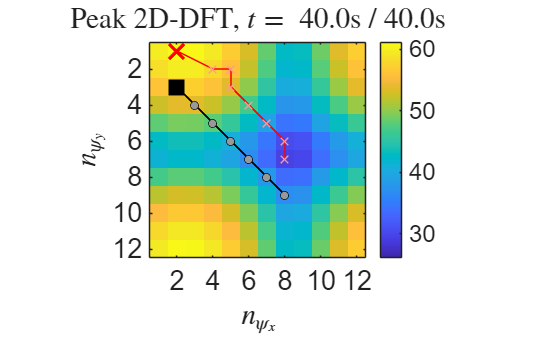

%% Animation
figure;
h_img = imagesc(1:EnvPars.T_x, 1:EnvPars.T_y, R_max_per_frame(:,:,1));
axis square; colorbar; hold on;

% Common color scale across frames
clim([min(R_max_per_frame(:)), max(R_max_per_frame(:))]);

% % --- Agent (black) ---
% Trail of past agent actions
h_trail_agent = plot(agent_tx(1), agent_ty(1), '-', ...
                     'Color', [0 0 0 0.4], 'LineWidth', 1.2);
% Past action markers (dim)
h_past_agent  = plot(agent_tx(1), agent_ty(1), 'ko', 'MarkerSize', 6, ...
                     'MarkerFaceColor',[0.6 0.6 0.6], 'MarkerEdgeColor','k');
%Current agent action (bright)
h_agent       = plot(agent_tx(1), agent_ty(1), 'ks', 'MarkerSize', 14, ...
                     'MarkerFaceColor', 'k', 'LineWidth', 1.5);

% --- Brute-force optimum (red) ---
% Trail of past optima
h_trail_brute_force   = plot(tx_brute_force_per_frame(1), ty_brute_force_per_frame(1), '-', ...
                     'Color', [1 0 0 0.4], 'LineWidth', 1.2);
% Past optimum markers (dim red)
h_past_brute_force    = plot(tx_brute_force_per_frame(1), ty_brute_force_per_frame(1), 'rx', ...
                     'MarkerSize', 8, 'LineWidth', 1.0, ...
                     'Color', [1 0.6 0.6]);
% Current optimum (bright red)
h_opt_brute_force         = plot(tx_brute_force_per_frame(1), ty_brute_force_per_frame(1), 'rx', ...
                     'MarkerSize', 16, 'LineWidth', 2.5);

xlabel('$n_{\psi_x}$','Interpreter','latex');
ylabel('$n_{\psi_y}$','Interpreter','latex');
h_title = title(sprintf('Peak 2D-DFT, $t=$ %.1fs / %.1fs', delta_time, time_simul), ...
                'Interpreter','latex');
% legend([h_agent, h_opt_brute_force], {'Agent action','Brute-force optimum'}, ...
%        'Location','southwest','Interpreter','latex');
set(gca,'FontSize',font);

xlim([0.5 EnvPars.T_x+0.5]); ylim([0.5 EnvPars.T_y+0.5]);

for k = 1:Nsteps-1
    set(h_img, 'CData', R_max_per_frame(:,:,k));
    
    % Agent: trail, past markers, current
    set(h_trail_agent, 'XData', agent_tx(1:k),          'YData', agent_ty(1:k));
    set(h_past_agent,  'XData', agent_tx(1:max(1,k-1)), 'YData', agent_ty(1:max(1,k-1)));
    set(h_agent,       'XData', agent_tx(k),            'YData', agent_ty(k));
    
    % Optimum: trail, past markers, current
    set(h_trail_brute_force,   'XData', tx_brute_force_per_frame(1:k),          'YData', ty_brute_force_per_frame(1:k));
    set(h_past_brute_force,    'XData', tx_brute_force_per_frame(1:max(1,k-1)), 'YData', ty_brute_force_per_frame(1:max(1,k-1)));
    set(h_opt_brute_force,         'XData', tx_brute_force_per_frame(k),            'YData', ty_brute_force_per_frame(k));
    
    set(h_title, 'String', sprintf('Peak 2D-DFT, $t=$ %.1fs / %.1fs', k*delta_time, time_simul));
    drawnow;
    if k < Nsteps
        pause(0.05);
    end
end

#### Animation of MU psi_x_traj vs Brute force vs Agent

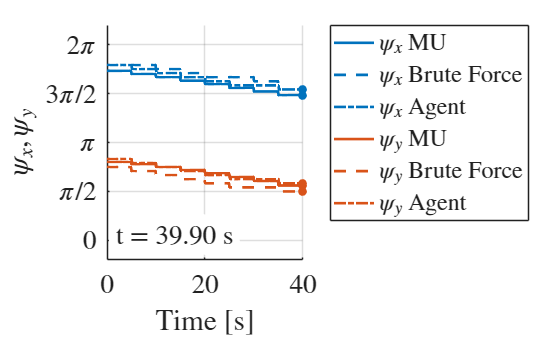


figure;
hold on;
grid on;

xlabel('Time [s]','Interpreter','latex');
ylabel('$\psi_x,\,\psi_y$','Interpreter','latex');
%title('$\psi_x$ Real vs Brute Force','Interpreter','latex');

% Axis limits (auto-adapt nicely)
xmin = min(t);
xmax = max(t);

ymin = 0;%min([psi_x_real_log(:); psi_x_brute_force_per_frame(:)]);
ymax = 2*pi;%max([psi_x_real_log(:); psi_y_brute_force_per_frame(:)]);

% Add small margins
margin = 0.1*(ymax - ymin + eps);
ylim([ymin - margin, ymax + margin]);
xlim([xmin xmax]);

% Initialize lines
%MU
h_traj_psi_x = plot(t(1), psi_x_traj_log(1), '-','Color','#0072BD', 'LineWidth', 2);
h_traj_psi_y = plot(t(1), psi_y_traj_log(1), '-','Color','#D95319', 'LineWidth', 2);
%Brute force
h_psi_x_brute_force  = plot(t(1), psi_x_brute_force_per_frame(1), '--','Color','#0072BD', 'LineWidth', 2);
h_psi_y_brute_force  = plot(t(1), psi_y_brute_force_per_frame(1), '--','Color','#D95319', 'LineWidth', 2);
% Agent
h_psi_x_agent  = plot(t(1), psi_x_agent_est_log(1), '-.','Color','#0072BD', 'LineWidth', 2);
h_psi_y_agent  = plot(t(1), psi_y_agent_est_log(1), '-.','Color','#D95319', 'LineWidth', 2);


% Moving markers (like two actors on stage)
%MU
h_true_psi_x_pt = plot(t(1), psi_x_traj_log(1), 'o','Color', '#0072BD', 'MarkerFaceColor','#0072BD');
h_true_psi_y_pt = plot(t(1), psi_y_traj_log(1), 'o','Color', '#D95319', 'MarkerFaceColor','#D95319');
%Brute force
h_psi_x_brute_force_pt  = plot(t(1), psi_x_brute_force_per_frame(1), 'o','Color','#0072BD', 'MarkerFaceColor','#0072BD');
h_psi_y_brute_force_pt  = plot(t(1), psi_y_brute_force_per_frame(1), 'o','Color','#D95319', 'MarkerFaceColor','#D95319');
%Agent
h_psi_x_agent_pt  = plot(t(1), psi_x_agent_est_log(1), 'o','Color','#0072BD', 'MarkerFaceColor','#0072BD');
h_psi_y_agent_pt  = plot(t(1), psi_y_agent_est_log(1), 'o','Color','#D95319', 'MarkerFaceColor','#D95319');

legend([h_traj_psi_x,h_psi_x_brute_force,h_psi_x_agent,h_traj_psi_y,h_psi_y_brute_force,h_psi_y_agent],...
    {'$\psi_x$ MU','$\psi_x$ Brute Force','$\psi_x$ Agent','$\psi_y$ MU','$\psi_y$ Brute Force','$\psi_y$ Agent'},'Interpreter','latex','Location','Northeastout');

set(gca, 'YTick', [0,pi/2,pi,3*pi/2,2*pi]);
y_ticks=cell(1,5);
x_ticks{1}="$0$";
x_ticks{2}="$\pi/2$";
x_ticks{3}="$\pi$";
x_ticks{4}="$3\pi/2$";
x_ticks{5}="$2\pi$";
set(gca, 'YTickLabel', x_ticks, 'TickLabelInterpreter', 'latex');

% Time label
h_time = text(xmin + 0.03*(xmax-xmin), ymin+ 0.03*(ymax-ymin), ...
    sprintf('$t = %.2f$ s', t(1)), ...
    'FontSize', font, ...
    'BackgroundColor', 'w','Interpreter','latex');

set(gca,'FontSize',font);

%% Animation loop
for k = 1:Nsteps-1
    
    % Update full curves up to time k
    %MU
    set(h_traj_psi_x, 'XData', t(1:k), 'YData', psi_x_traj_log(1:k));
    set(h_traj_psi_y, 'XData', t(1:k), 'YData', psi_y_traj_log(1:k));
    %Brute Force
    set(h_psi_x_brute_force,  'XData', t(1:k), 'YData', psi_x_brute_force_per_frame(1:k));
    set(h_psi_y_brute_force,  'XData', t(1:k), 'YData', psi_y_brute_force_per_frame(1:k));
    %Agent
    set(h_psi_x_agent,  'XData', t(1:k), 'YData', psi_x_agent_est_log(1:k));
    set(h_psi_y_agent,  'XData', t(1:k), 'YData', psi_y_agent_est_log(1:k));
    
    % Update moving markers
    %MU
    set(h_true_psi_x_pt, 'XData', t(k), 'YData', psi_x_traj_log(k));
    set(h_true_psi_y_pt, 'XData', t(k), 'YData', psi_y_traj_log(k));
    %Brute Force
    set(h_psi_x_brute_force_pt,  'XData', t(k), 'YData', psi_x_brute_force_per_frame(k));
    set(h_psi_y_brute_force_pt,  'XData', t(k), 'YData', psi_y_brute_force_per_frame(k));
    %Agent
    set(h_psi_x_agent_pt,  'XData', t(k), 'YData', psi_x_agent_est_log(k));
    set(h_psi_y_agent_pt,  'XData', t(k), 'YData', psi_y_agent_est_log(k));
    
    % Update time text
    set(h_time, 'String', sprintf('t = %.2f s', t(k)));
    
    drawnow;
    
    % % Optional real-time pacing
    % if k < length(t)
    %     pause((t(k+1) - t(k)));
    % end
end

#### Animation of MU psi_x_real vs Brute Force


figure;
hold on;
grid on;

xlabel('Time [s]','Interpreter','latex');
ylabel('$\psi_x$','Interpreter','latex');
%title('$\psi_x$ Real vs Brute Force','Interpreter','latex');

% Axis limits (auto-adapt nicely)
xmin = min(t);
xmax = max(t);

ymin = 0;%min([psi_x_real_log(:); psi_x_brute_force_per_frame(:)]);
ymax = 2*pi;%max([psi_x_real_log(:); psi_y_brute_force_per_frame(:)]);

% Add small margins
margin = 0.1*(ymax - ymin + eps);
ylim([ymin - margin, ymax + margin]);
xlim([xmin xmax]);

% Initialize lines
h_traj_psi_x = plot(t(1), psi_x_traj_log(1), '-','Color','#0072BD', 'LineWidth', 2);
h_traj_psi_y = plot(t(1), psi_y_traj_log(1), '-','Color','#D95319', 'LineWidth', 2);
h_psi_x_brute_force  = plot(t(1), psi_x_brute_force_per_frame(1), '--','Color','#0072BD', 'LineWidth', 2);
h_psi_y_brute_force  = plot(t(1), psi_y_brute_force_per_frame(1), '--','Color','#D95319', 'LineWidth', 2);



% Moving markers (like two actors on stage)
h_true_psi_x_pt = plot(t(1), psi_x_traj_log(1), 'o','Color', '#0072BD', 'MarkerFaceColor','#0072BD');
h_true_psi_y_pt = plot(t(1), psi_y_traj_log(1), 'o','Color', '#D95319', 'MarkerFaceColor','#D95319');
h_psi_x_brute_force_pt  = plot(t(1), psi_x_brute_force_per_frame(1), 'o','Color','#0072BD', 'MarkerFaceColor','#0072BD');
h_psi_y_brute_force_pt  = plot(t(1), psi_y_brute_force_per_frame(1), 'o','Color','#D95319', 'MarkerFaceColor','#D95319');

legend([h_traj_psi_x,h_psi_x_brute_force,h_traj_psi_y,h_psi_y_brute_force],...
    {'$\psi_x$ MU','$\psi_x$ Brute Force','$\psi_y$ MU','$\psi_y$ Brute Force'},'Interpreter','latex','Location','Northeastout');

set(gca, 'YTick', [0,pi/2,pi,3*pi/2,2*pi]);
y_ticks=cell(1,5);
x_ticks{1}="$0$";
x_ticks{2}="$\pi/2$";
x_ticks{3}="$\pi$";
x_ticks{4}="$3\pi/2$";
x_ticks{5}="$2\pi$";
set(gca, 'YTickLabel', x_ticks, 'TickLabelInterpreter', 'latex');

% Time label
h_time = text(xmin + 0.03*(xmax-xmin), ymin+ 0.03*(ymax-ymin), ...
    sprintf('$t = %.2f$ s', t(1)), ...
    'FontSize', font, ...
    'BackgroundColor', 'w','Interpreter','latex');

set(gca,'FontSize',font);

%% Animation loop
for k = 1:Nsteps-1
    
    % Update full curves up to time k
    set(h_traj_psi_x, 'XData', t(1:k), 'YData', psi_x_traj_log(1:k));
    set(h_traj_psi_y, 'XData', t(1:k), 'YData', psi_y_traj_log(1:k));
    set(h_psi_x_brute_force,  'XData', t(1:k), 'YData', psi_x_brute_force_per_frame(1:k));
    set(h_psi_y_brute_force,  'XData', t(1:k), 'YData', psi_y_brute_force_per_frame(1:k));
    
    % Update moving markers
    set(h_true_psi_x_pt, 'XData', t(k), 'YData', psi_x_traj_log(k));
    set(h_true_psi_y_pt, 'XData', t(k), 'YData', psi_y_traj_log(k));
    set(h_psi_x_brute_force_pt,  'XData', t(k), 'YData', psi_x_brute_force_per_frame(k));
    set(h_psi_y_brute_force_pt,  'XData', t(k), 'YData', psi_y_brute_force_per_frame(k));
    
    % Update time text
    set(h_time, 'String', sprintf('t = %.2f s', t(k)));
    
    drawnow;
    
    % % Optional real-time pacing
    % if k < length(t)
    %     pause((t(k+1) - t(k)));
    % end
end

#### Animation $\psi$ plane Brute Force 


% Common color scale across both panels and all frames
cmin = min([R_brute_force_per_frame(:); R_brute_force_per_frame(:)]);
cmax = max([R_brute_force_per_frame(:); R_brute_force_per_frame(:)]);

%% Build the angle axes for case "true" and "est" at each frame
% These shift with the agent's t_psi via the bin-shift formula.
psi_x_axis_per_frame = zeros(EnvPars.N_x, Nsteps);
psi_y_axis_per_frame = zeros(EnvPars.N_y, Nsteps);
for k = 1:Nsteps
    psi_x_axis_per_frame(:,k) = 2*pi * ((1:EnvPars.N_x) - 1 + (tx_brute_force_per_frame(k)-1)/EnvPars.T_x) / EnvPars.N_x;
    psi_y_axis_per_frame(:,k) = 2*pi * ((1:EnvPars.N_y) - 1 + (tx_brute_force_per_frame(k)-1)/EnvPars.T_y) / EnvPars.N_y;
end

figure;
h_img = imagesc(1:EnvPars.T_x, 1:EnvPars.T_y, R_max_per_frame(:,:,1));
axis square; colorbar; hold on;

% Common color scale across frames
clim([min(R_max_per_frame(:)), max(R_max_per_frame(:))]);

% % --- Agent (black) ---
% % Trail of past agent actions
% h_trail_agent = plot(agent_tx(1), agent_ty(1), '-', ...
%                      'Color', [0 0 0 0.4], 'LineWidth', 1.2);
% % Past action markers (dim)
% h_past_agent  = plot(agent_tx(1), agent_ty(1), 'ko', 'MarkerSize', 6, ...
%                      'MarkerFaceColor',[0.6 0.6 0.6], 'MarkerEdgeColor','k');
% Current agent action (bright)
% h_agent       = plot(agent_tx(1), agent_ty(1), 'ks', 'MarkerSize', 14, ...
%                      'MarkerFaceColor', 'k', 'LineWidth', 1.5);

% --- Brute-force optimum (red) ---
% Trail of past optima
h_trail_brute_force   = plot(tx_brute_force_per_frame(1), ty_brute_force_per_frame(1), '-', ...
                     'Color', [1 0 0 0.4], 'LineWidth', 1.2);
% Past optimum markers (dim red)
h_past_brute_force    = plot(tx_brute_force_per_frame(1), ty_brute_force_per_frame(1), 'rx', ...
                     'MarkerSize', 8, 'LineWidth', 1.0, ...
                     'Color', [1 0.6 0.6]);
% Current optimum (bright red)
h_opt_brute_force         = plot(tx_brute_force_per_frame(1), ty_brute_force_per_frame(1), 'rx', ...
                     'MarkerSize', 16, 'LineWidth', 2.5);

xlabel('$n_{\psi_x}$','Interpreter','latex');
ylabel('$n_{\psi_y}$','Interpreter','latex');
h_title = title(sprintf('Peak 2D-DFT, $t=$ %.1fs / %.1fs', delta_time, time_simul), ...
                'Interpreter','latex');
% legend([h_agent, h_opt_brute_force], {'Agent action','Brute-force optimum'}, ...
       % 'Location','northwest','Interpreter','latex');
set(gca,'FontSize',font);

xlim([0.5 EnvPars.T_x+0.5]); ylim([0.5 EnvPars.T_y+0.5]);

for k = 1:Nsteps-1
    set(h_img, 'CData', R_max_per_frame(:,:,k));
    
    % % Agent: trail, past markers, current
    % set(h_trail_agent, 'XData', agent_tx(1:k),          'YData', agent_ty(1:k));
    % set(h_past_agent,  'XData', agent_tx(1:max(1,k-1)), 'YData', agent_ty(1:max(1,k-1)));
    % set(h_agent,       'XData', agent_tx(k),            'YData', agent_ty(k));
    
    % Optimum: trail, past markers, current
    set(h_trail_brute_force,   'XData', tx_brute_force_per_frame(1:k),          'YData', ty_brute_force_per_frame(1:k));
    set(h_past_brute_force,    'XData', tx_brute_force_per_frame(1:max(1,k-1)), 'YData', ty_brute_force_per_frame(1:max(1,k-1)));
    set(h_opt_brute_force,         'XData', tx_brute_force_per_frame(k),            'YData', ty_brute_force_per_frame(k));
    
    set(h_title, 'String', sprintf('Peak 2D-DFT, $t=$ %.1fs / %.1fs', k*delta_time, time_simul));
    drawnow;
    if k < Nsteps
        pause(0.05);
    end
end

#### Animation 2D-DFT Brute Force  

%% Animation
figure;

h_img_true = imagesc(psi_x_axis_per_frame(:,1), ...
                     psi_y_axis_per_frame(:,1), ...
                     R_brute_force_per_frame(:,:,1));
axis xy square; colorbar; clim([cmin cmax]); hold on;
h_truth_L = plot(psi_x_traj_log(1), psi_y_traj_log(1), 'rx', ...
                 'MarkerSize', 14, 'LineWidth', 2);
h_psi_x_brute_force = plot(psi_x_traj_log(1), psi_y_traj_log(1), 'rx', ...
                 'MarkerSize', 14, 'LineWidth', 2);

xlabel('$\psi_x$ [rad]','Interpreter','latex');
ylabel('$\psi_y$ [rad]','Interpreter','latex');
h_title_L = title(sprintf('2D-DFT Brute Force, step %%.1fs / %.1fs', 1, Nsteps), ...
                  'Interpreter','latex');
xlim([0, 2.2*pi]); ylim([0, 2.2*pi]);
set(gca,'FontSize',font);



%% Animation loop
for k = 1:Nsteps-1
    set(h_img_true, 'XData', psi_x_axis_per_frame(:,k), ...
                    'YData', psi_y_axis_per_frame(:,k), ...
                    'CData', R_brute_force_per_frame(:,:,k));
    set(h_truth_L,  'XData', psi_x_traj_log(k), 'YData', psi_y_traj_log(k));
    set(h_title_L,  'String', sprintf('2D-DFT Brute Force, $t=$ %.1fs / %.1fs', delta_time*k, time_simul));
    drawnow;
    if k < Nsteps
        pause(0.01);
    end
end

%% Animation: R from true vs. estimated steering vector
% Left  panel: R using a_psi_x_y from the true (psi_x_real, psi_y_real)
% Right panel: R using a_psi_x_y from the estimated (psi_x_est, psi_y_est)
% Both panels use the agent's chosen t_psi at each step.

% Nsteps = numel(psi_x_real_log);

% % Pre-compute |R| for both cases at every step
% R_true_per_frame = zeros(EnvPars.N_x, EnvPars.N_y, Nsteps);
R_agent_per_frame  = zeros(EnvPars.N_x, EnvPars.N_y, Nsteps);

% Continuous (non-codebook) phase preset that focuses the SIM at angle (psi_x, psi_y)
makeUpFromAngle = @(psi_x, psi_y) diag(exp(-1i * ( ...
    (n_x') * psi_x + (n_y') * psi_y )));

for k = 1:Nsteps
    % Common true steering vector
    a_psi_x_true = exp(1i * psi_x_traj(k) * ((1:EnvPars.N_x) - 1))';
    a_psi_y_true = exp(1i * psi_y_traj(k) * ((1:EnvPars.N_y) - 1))';
    a_true = kron(a_psi_y_true, a_psi_x_true);
    % a_psi_x_true = exp(1i * 1/(EnvPars.N_x*EnvPars.T_x) * ((1:EnvPars.N_x) - 1))';
    % a_psi_y_true = exp(1i * 1/(EnvPars.N_x*EnvPars.T_x) * ((1:EnvPars.N_y) - 1))';
    % a_true = kron(a_psi_y_true, a_psi_x_true);

    % % --- Brute force case: SIM focused at the shifted angle ---
    % v_0=EnvPars.U_func(1:EnvPars.N,(tx_brute_force_per_frame(k))*(ty_brute_force_per_frame(k)));
    % Up_true=diag(v_0');
    % G_Up_true = EnvPars.G * Up_true;
    % r_true    = sqrt(db2pow(EnvPars.SNR_dB)) * G_Up_true * a_true;
    % R_true_per_frame(:,:,k) = reshape(abs(r_true), [EnvPars.N_x, EnvPars.N_y]);

    % --- Estimated case: SIM focused at the agent's estimate ---
    % v_0=EnvPars.U_func(1:EnvPars.N,(agent_tx(k)+1)*(agent_ty(k)+1));
    v_0=EnvPars.U_func(1:EnvPars.N,action_agent(k)+1);
    Up_est=diag(v_0');
    G_Up_est  = EnvPars.G * Up_est;
    r_est     = sqrt(db2pow(EnvPars.SNR_dB)) * G_Up_est * a_true;
    R_agent_per_frame(:,:,k) = ((reshape(abs(r_est), [EnvPars.N_x, EnvPars.N_y])));
end

% Common color scale across both panels and all frames
cmin = min([R_brute_force_per_frame(:); R_brute_force_per_frame(:)]);
cmax = max([R_brute_force_per_frame(:); R_brute_force_per_frame(:)]);

%% Build the angle axes for case "true" and "est" at each frame
% These shift with the agent's t_psi via the bin-shift formula.
psi_x_axis_per_frame = zeros(EnvPars.N_x, Nsteps);
psi_y_axis_per_frame = zeros(EnvPars.N_y, Nsteps);
for k = 1:Nsteps
    t_psi_k = actions(k)+1;
    tx_k = EnvPars.t_x(t_psi_k);
    ty_k = EnvPars.t_y(t_psi_k);
    psi_x_axis_per_frame(:,k) = 2*pi * ((1:EnvPars.N_x) - 1 + (tx_k-1)/EnvPars.T_x) / EnvPars.N_x;
    psi_y_axis_per_frame(:,k) = 2*pi * ((1:EnvPars.N_y) - 1 + (ty_k-1)/EnvPars.T_y) / EnvPars.N_y;
end

%% Animation
figure('Position', [100 100 1100 480]);

% --- Left subplot: true ---
subplot(1,2,1);
h_img_true = imagesc(psi_x_axis_per_frame(:,1), ...
                     psi_y_axis_per_frame(:,1), ...
                     R_brute_force_per_frame(:,:,1));
axis xy; colorbar; clim([cmin cmax]); hold on;
h_truth_L = plot(psi_x_traj(1), psi_y_traj(1), 'rx', ...
                 'MarkerSize', 14, 'LineWidth', 2);
h_psi_x_brute_force = plot(psi_x_brute_force_per_frame(1), psi_y_brute_force_per_frame(1), 'rx', ...
                 'MarkerSize', 14, 'LineWidth', 2);

xlabel('$\psi_x$ [rad]','Interpreter','latex');
ylabel('$\psi_y$ [rad]','Interpreter','latex');
h_title_L = title(sprintf('$|R|$ from true $a$, step %d / %d', 1, Nsteps), ...
                  'Interpreter','latex');
xlim([0, 2.2*pi]); ylim([0, 2*pi]);
set(gca,'FontSize',font);

% --- Right subplot: estimated ---
subplot(1,2,2);
h_img_est = imagesc(psi_x_axis_per_frame(:,1), ...
                    psi_y_axis_per_frame(:,1), ...
                    R_brute_force_per_frame(:,:,1));
axis xy; colorbar; clim([cmin cmax]); hold on;
h_est_R = plot(psi_x_agent_est_log(1), psi_y_agent_est_log(1), 'gs', ...
               'MarkerSize', 12, 'LineWidth', 2, 'MarkerFaceColor', 'none');
xlabel('$\psi_x$ [rad]','Interpreter','latex');
ylabel('$\psi_y$ [rad]','Interpreter','latex');
h_title_R = title(sprintf('$|R|$ from estimated $a$, step %d / %d', 1, Nsteps), ...
                  'Interpreter','latex');
xlim([0, 2*pi]); ylim([0, 2*pi]);
set(gca,'FontSize',font);

%% Animation loop
for k = 1:Nsteps
    set(h_img_true, 'XData', psi_x_axis_per_frame(:,k), ...
                    'YData', psi_y_axis_per_frame(:,k), ...
                    'CData', R_true_per_frame(:,:,k));
    set(h_truth_L,  'XData', psi_x_traj(k), 'YData', psi_x_traj(k));
    set(h_title_L,  'String', sprintf('$|R|$ from true $a$, step %d / %d', k, Nsteps));

    set(h_img_est,  'XData', psi_x_axis_per_frame(:,k), ...
                    'YData', psi_y_axis_per_frame(:,k), ...
                    'CData', R_brute_force_per_frame(:,:,k));
    set(h_est_R,    'XData', psi_x_agent_est_log(k), 'YData', psi_y_agent_est_log(k));
    set(h_title_R,  'String', sprintf('$|R|$ from estimated $a$, step %d / %d', k, Nsteps));

    drawnow;
    if k < Nsteps
        pause(0.05);
    end
end



%% Animation of psi_x_real vs psi_x_est

figure;
hold on;
grid on;

xlabel('Time [s]','Interpreter','latex');
ylabel('$\psi_x$','Interpreter','latex');
title('$\psi_x$ Real vs Estimated','Interpreter','latex');

% Axis limits (auto-adapt nicely)
xmin = min(t);
xmax = max(t);

ymin = min([psi_x_real_log(:); psi_x_agent_est_log(:)]);
ymax = max([psi_x_real_log(:); psi_x_agent_est_log(:)]);

% Add small margins
margin = 0.1*(ymax - ymin + eps);
ylim([ymin - margin, ymax + margin]);
xlim([xmin xmax]);

% Initialize lines
h_traj_psi_x = plot(t(1), psi_x_real_log(1), 'b-', 'LineWidth', 2);
h_est  = plot(t(1), psi_x_agent_est_log(1), 'r--', 'LineWidth', 2);



% Moving markers
h_true_psi_x_pt = plot(t(1), psi_x_real_log(1), 'bo', 'MarkerFaceColor','b');
h_est_pt  = plot(t(1), psi_x_agent_est_log(1), 'ro', 'MarkerFaceColor','r');

legend([h_traj_psi_x,h_est],{'Real','Estimated'});

set(gca, 'YTick', [0,pi/2,pi,3*pi/2,2*pi]);
y_ticks=cell(1,5);
x_ticks{1}="$0$";
x_ticks{2}="$\pi/2$";
x_ticks{3}="$\pi$";
x_ticks{4}="$3\pi/2$";
x_ticks{5}="$2\pi$";
set(gca, 'YTickLabel', x_ticks, 'TickLabelInterpreter', 'latex');

% Time label
h_time = text(xmin + 0.02*(xmax-xmin), ymax, ...
    sprintf('$t = %.2f$ s', t(1)), ...
    'FontSize', font, ...
    'BackgroundColor', 'w','Interpreter','latex');

set(gca,'FontSize',font);

%% Animation loop
for k = 1:length(t)
    
    % Update full curves up to time k
    set(h_traj_psi_x, 'XData', t(1:k), 'YData', psi_x_real_log(1:k));
    set(h_est,  'XData', t(1:k), 'YData', psi_x_agent_est_log(1:k));
    
    % Update moving markers
    set(h_true_psi_x_pt, 'XData', t(k), 'YData', psi_x_real_log(k));
    set(h_est_pt,  'XData', t(k), 'YData', psi_x_agent_est_log(k));
    
    % Update time text
    set(h_time, 'String', sprintf('t = %.2f s', t(k)));
    
    drawnow;
    
    % % Optional real-time pacing
    % if k < length(t)
    %     pause((t(k+1) - t(k)));
    % end
end


#### Animation

figure;
h_img = imagesc(1:EnvPars.T_x, 1:EnvPars.T_y, R_max_per_frame(:,:,1)');
axis xy; colorbar; hold on;

% Common color scale across frames
clim([min(R_max_per_frame(:)), max(R_max_per_frame(:))]);

% Trail of past agent actions
h_trail = plot(agent_tx(1), agent_ty(1), '-', 'Color', [0 0 0 0.4], 'LineWidth', 1.2);
% Past action markers (dim)
h_past  = plot(agent_tx(1), agent_ty(1), 'ko', 'MarkerSize', 6, ...
               'MarkerFaceColor',[0.6 0.6 0.6], 'MarkerEdgeColor','k');
% Current agent action (bright)
h_agent = plot(agent_tx(1), agent_ty(1), 'ks', 'MarkerSize', 14, ...
               'MarkerFaceColor', 'k', 'LineWidth', 1.5);
% Current brute-force optimum
h_opt_brute_force   = plot(tx_brute_force_per_frame(1), ty_brute_force_per_frame(1), 'rx', ...
               'MarkerSize', 16, 'LineWidth', 2.5);

xlabel('$t_{\psi_x}+1$','Interpreter','latex');
ylabel('$t_{\psi_y}+1$','Interpreter','latex');
h_title = title(sprintf('Peak $|R|$, frame %d / %d', 1, numEpisodesToTest), ...
                'Interpreter','latex');
legend([h_agent, h_opt_brute_force], {'Agent action','Brute-force optimum'}, ...
       'Location','best','Interpreter','latex');
set(gca,'FontSize',font);

xlim([0.5 EnvPars.T_x+0.5]); ylim([0.5 EnvPars.T_y+0.5]);

for k = 1:numEpisodesToTest
    set(h_img,   'CData', R_max_per_frame(:,:,k)');
    set(h_trail, 'XData', agent_tx(1:k), 'YData', agent_ty(1:k));
    set(h_past,  'XData', agent_tx(1:max(1,k-1)), 'YData', agent_ty(1:max(1,k-1)));
    set(h_agent, 'XData', agent_tx(k), 'YData', agent_ty(k));
    set(h_opt_brute_force,   'XData', tx_brute_force_per_frame(k), 'YData', ty_brute_force_per_frame(k));
    set(h_title, 'String', sprintf('Peak $|R|$, frame %d / %d', k, numEpisodesToTest));
    drawnow;
    if k < numEpisodesToTest
        pause(0.05);
    end
end

%% Animation of psi_y_real vs psi_y_est

figure;
hold on;
grid on;

xlabel('Time [s]','Interpreter','latex');
ylabel('$\psi_y$','Interpreter','latex');
title('$\psi_y$ Real vs Estimated','Interpreter','latex');

% Axis limits (auto-adapt nicely)
xmin = min(t);
xmax = max(t);

ymin = min([psi_y_real(:); psi_y_est(:)]);
ymax = max([psi_y_real(:); psi_y_est(:)]);

% Add small margins
margin = 0.1*(ymax - ymin + eps);
ylim([ymin - margin, ymax + margin]);
xlim([xmin xmax]);

% Initialize lines
h_traj_psi_x = plot(t(1), psi_y_real(1), 'b-', 'LineWidth', 2);
h_est  = plot(t(1), psi_y_est(1), 'r--', 'LineWidth', 2);

% Moving markers
h_true_psi_x_pt = plot(t(1), psi_y_real(1), 'bo', 'MarkerFaceColor','b');
h_est_pt  = plot(t(1), psi_y_est(1), 'ro', 'MarkerFaceColor','r');

legend([h_traj_psi_x,h_est],{'Real','Estimated'});

% Y ticks in radians
set(gca, 'YTick', [0,pi/2,pi,3*pi/2,2*pi]);
y_ticks = cell(1,5);
y_ticks{1} = "$0$";
y_ticks{2} = "$\pi/2$";
y_ticks{3} = "$\pi$";
y_ticks{4} = "$3\pi/2$";
y_ticks{5} = "$2\pi$";
set(gca, 'YTickLabel', y_ticks, 'TickLabelInterpreter', 'latex');

% Time label
h_time = text(xmin + 0.02*(xmax-xmin), ymax, ...
    sprintf('$t = %.2f$ s', t(1)), ...
    'FontSize', font, ...
    'BackgroundColor', 'w', ...
    'Interpreter','latex');

set(gca,'FontSize',font);

%% Animation loop
for k = 1:length(t)
    
    % Update full curves
    set(h_traj_psi_x, 'XData', t(1:k), 'YData', psi_y_real(1:k));
    set(h_est,  'XData', t(1:k), 'YData', psi_y_est(1:k));
    
    % Update markers
    set(h_true_psi_x_pt, 'XData', t(k), 'YData', psi_y_real(k));
    set(h_est_pt,  'XData', t(k), 'YData', psi_y_est(k));
    
    % Update time text
    set(h_time, 'String', sprintf('$t = %.2f$ s', t(k)));
    
    drawnow;
    
    if k < length(t)
        pause(t(k+1) - t(k));
    end
end


#### Deterministic Evaluation

%% Brute-force action-landscape sweep at a fixed true angle
% For a chosen true angle, evaluate all T phase presets t_psi and
% record both the peak DFT magnitude and the resulting estimation error,
% averaged over noise realizations.

% Choose a representative true angle to probe.
% Option A: pick a fixed test angle.
psi_x_true_probe = pi/4;
psi_y_true_probe = pi/4;
% Option B (alternative): use one snapshot of the random-walk trajectory.
% [psi_x_true_probe, psi_y_true_probe] = computeAnglesFromMU(pos_MU_traj(:,1), EnvPars);

Nrep = 50;   % noise realizations per phase preset

R_max_array = zeros(EnvPars.T_x, EnvPars.T_y);
err_array   = zeros(EnvPars.T_x, EnvPars.T_y);

% Pre-build the true steering vector once (independent of t_psi)
a_psi_x = exp(1i * psi_x_true_probe * ((1:EnvPars.N_x) - 1))';
a_psi_y = exp(1i * psi_y_true_probe * ((1:EnvPars.N_y) - 1))';
a_psi_x_y = kron(a_psi_y, a_psi_x);

for t_psi = 1:EnvPars.T
    tx = EnvPars.t_x(t_psi);
    ty = EnvPars.t_y(t_psi);

    % Phase preset (same across noise realizations)
    v0 = EnvPars.U_func(1:EnvPars.N, t_psi);
    Upsilon = diag(v0');
    G_Upsilon = EnvPars.G * Upsilon;

    R_max_acc = 0;
    err_acc   = 0;


    u = 0;%(randn(EnvPars.N,1) + 1i*randn(EnvPars.N,1)) / sqrt(2);
    r = sqrt(db2pow(EnvPars.SNR_dB)) * G_Upsilon * a_psi_x_y + u;

    R = reshape(abs(r), [EnvPars.N_x, EnvPars.N_y]);
    [maxR, linear_idx] = max(R.^2, [], 'all');
    n_psi_x_max = ceil(linear_idx / EnvPars.N_x);
    n_psi_y_max = linear_idx - (n_psi_x_max - 1) * EnvPars.N_x;

    psi_x_est = mod(2*pi * (n_psi_x_max + tx/EnvPars.T_x) / EnvPars.N_x, 2*pi);
    psi_y_est = mod(2*pi * (n_psi_y_max + ty/EnvPars.T_y) / EnvPars.N_y, 2*pi);

    err = 0.5 * (abs(psi_x_true_probe - psi_x_est) + ...
        abs(psi_y_true_probe - psi_y_est));

    R_max_acc = R_max_acc + maxR;
    err_acc   = err_acc + err;


    R_max_array(tx+1, ty+1) = maxR;
    err_array(tx+1, ty+1)   = err;
end

% Identify the brute-force optima
[~, idx_max_R]   = max(R_max_array(:));
[~, idx_min_err] = min(err_array(:));
[tx_opt_R,   ty_opt_R]   = ind2sub(size(R_max_array), idx_max_R);
[tx_opt_err, ty_opt_err] = ind2sub(size(err_array),   idx_min_err);

%% Plot the two heatmaps side by side
figure;
imagesc(1:EnvPars.T_x, 1:EnvPars.T_y, R_max_array');
axis xy; colorbar; hold on;
plot(tx_opt_R, ty_opt_R, 'rx', 'MarkerSize', 14, 'LineWidth', 2);
xlabel('$n_{\psi_x}$','Interpreter','latex');
ylabel('$n_{\psi_y}$','Interpreter','latex');
title('Peak |2D-DFT|','Interpreter','latex');
set(gca,'FontSize',font);

%% Filled cells, blank elsewhere
% Bin width per axis
dx = 2*pi / EnvPars.N_x;
dy = 2*pi / EnvPars.N_y;

% Common colorbar range
cmin = min([R_A_plot(:); R_B_plot(:)]);
cmax = max([R_A_plot(:); R_B_plot(:)]);

% Use a colormap to map R values to RGB triplets
cmap   = parula(256);
mapVal = @(v) cmap(max(1, min(256, round(1 + (v - cmin) / (cmax - cmin) * 255))), :);

x_ticks = 0 : pi/2 : 2*pi;
y_ticks = 0 : pi/2 : 2*pi;
x_tick_labels = arrayfun(@localPiTickLabel, x_ticks, 'UniformOutput', false);
y_tick_labels = arrayfun(@localPiTickLabel, y_ticks, 'UniformOutput', false);

figure;

% --- Subplot A: trivial preset ---
subplot(1,2,1);
hold on; box on;
for ix = 1:EnvPars.N_x
    for iy = 1:EnvPars.N_y
        cx = psi_x_orig_A(ix);
        cy = psi_y_orig_A(iy);
        val = R_A_plot(iy, ix);
        rectangle('Position', [cx - dx/2, cy - dy/2, dx, dy], ...
                  'FaceColor', mapVal(val), 'EdgeColor', 'none');
    end
end
% Tell the axes the true color range so the colorbar is correct
clim([cmin cmax]); colormap(cmap); colorbar;

% White dashed grid lines at cell boundaries (one extra line on each side)
% For case A: boundaries at psi_x_orig_A ± dx/2
x_boundaries_A = [psi_x_orig_A - dx/2, psi_x_orig_A(end) + dx/2];
y_boundaries_A = [psi_y_orig_A - dy/2, psi_y_orig_A(end) + dy/2];
for kx = 1:numel(x_boundaries_A)
    xline(x_boundaries_A(kx), '--w', 'LineWidth', 0.8);
end
for ky = 1:numel(y_boundaries_A)
    yline(y_boundaries_A(ky), '--w', 'LineWidth', 0.8);
end
plot(psi_x_true_probe, psi_y_true_probe, 'rx', 'MarkerSize', 14, 'LineWidth', 2);

xlim([0, 2*pi]); ylim([0, 2*pi]);
xlabel('$\psi_x$ [rad]','Interpreter','latex');
ylabel('$\psi_y$ [rad]','Interpreter','latex');
title(sprintf('$|R|^2$, trivial $t_\\psi=1$ ($t_{\\psi,x}=%d, t_{\\psi,y}=%d$)', tx_A, ty_A), ...
      'Interpreter','latex');
set(gca, 'XTick', x_ticks, 'XTickLabel', x_tick_labels, ...
         'YTick', y_ticks, 'YTickLabel', y_tick_labels, ...
         'TickLabelInterpreter','latex','FontSize',font, ...
         'Layer','top');   % keeps ticks above the rectangles

% --- Subplot B: optimal preset ---
subplot(1,2,2);
hold on; box on;
for ix = 1:EnvPars.N_x
    for iy = 1:EnvPars.N_y
        cx = psi_x_orig_B(ix);
        cy = psi_y_orig_B(iy);
        val = R_B_plot(iy, ix);
        rectangle('Position', [cx - dx/2, cy - dy/2, dx, dy], ...
                  'FaceColor', mapVal(val), 'EdgeColor', 'none');
    end
end
clim([cmin cmax]); colormap(cmap); colorbar;

x_boundaries_B = [psi_x_orig_B - dx/2, psi_x_orig_B(end) + dx/2];
y_boundaries_B = [psi_y_orig_B - dy/2, psi_y_orig_B(end) + dy/2];
for kx = 1:numel(x_boundaries_B)
    xline(x_boundaries_B(kx), '--w', 'LineWidth', 0.8);
end
for ky = 1:numel(y_boundaries_B)
    yline(y_boundaries_B(ky), '--w', 'LineWidth', 0.8);
end

plot(psi_x_true_probe, psi_y_true_probe, 'rx', 'MarkerSize', 14, 'LineWidth', 2);


xlim([0, 2*pi]);
ylim([0, 2*pi]);
xlabel('$\psi_x$ [rad]','Interpreter','latex');
ylabel('$\psi_y$ [rad]','Interpreter','latex');
title(sprintf('$|R|^2$, optimal $t_\\psi=%d$ ($t_{\\psi,x}=%d, t_{\\psi,y}=%d$)', t_psi_B, tx_B, ty_B), ...
      'Interpreter','latex');
set(gca, 'XTick', x_ticks, 'XTickLabel', x_tick_labels, ...
         'YTick', y_ticks, 'YTickLabel', y_tick_labels, ...
         'TickLabelInterpreter','latex','FontSize',font, ...
         'Layer','top');

%% Pre-compute per-frame heatmaps for the agent's trajectory
% Reuse the brute-force sweep, once per frame, using (psi_x_real(k), psi_y_real(k))
% as the probe angle. Stores R_max_array_k for each frame k.

R_max_per_frame = zeros(EnvPars.T_x, EnvPars.T_y, numEpisodesToTest);
tx_brute_force_per_frame = zeros(numEpisodesToTest, 1);
ty_brute_force_per_frame = zeros(numEpisodesToTest, 1);

for k = 1:numEpisodesToTest
    a_psi_x_k = exp(1i * psi_x_real(k) * ((1:EnvPars.N_x) - 1))';
    a_psi_y_k = exp(1i * psi_y_real(k) * ((1:EnvPars.N_y) - 1))';
    a_psi_x_y_k = kron(a_psi_y_k, a_psi_x_k);
    
    R_array_k = zeros(EnvPars.T_x, EnvPars.T_y);
    for t_psi = 1:EnvPars.T
        tx_loc = EnvPars.t_x(t_psi);
        ty_loc = EnvPars.t_y(t_psi);
        v0_loc = EnvPars.U_func(1:EnvPars.N, t_psi);
        Up_loc = diag(v0_loc');
        r_loc  = sqrt(db2pow(EnvPars.SNR_dB)) * EnvPars.G * Up_loc * a_psi_x_y_k;
        R_loc  = reshape(abs(r_loc), [EnvPars.N_x, EnvPars.N_y]);
        R_array_k(tx_loc+1, ty_loc+1) = max(R_loc, [], 'all');
    end
    R_max_per_frame(:,:,k) = R_array_k;
    
    [~, idx_k] = max(R_array_k(:));
    [tx_brute_force_per_frame(k), ty_brute_force_per_frame(k)] = ind2sub(size(R_array_k), idx_k);
end

%% Build the agent's chosen-action trajectory in (t_psi_x, t_psi_y) coordinates
% The agent fires multiple actions per episode; here we pick the LAST action
% taken in each episode (i.e., the policy's converged choice for that user position).
agent_tx = zeros(numEpisodesToTest, 1);
agent_ty = zeros(numEpisodesToTest, 1);
for k = 1:numEpisodesToTest
    nz = find(actions(:,k) ~= 0, 1, 'last');
    if isempty(nz), nz = 1; end
    action_agent = actions(nz, k);
    agent_tx(k) = EnvPars.t_x(action_agent) + 1;   % +1 to match the +1 offset in R_max_array
    agent_ty(k) = EnvPars.t_y(action_agent) + 1;
end

%% Animation
figure;
h_img = imagesc(1:EnvPars.T_x, 1:EnvPars.T_y, R_max_per_frame(:,:,1)');
axis xy; colorbar; hold on;

% Common color scale across frames
clim([min(R_max_per_frame(:)), max(R_max_per_frame(:))]);

% Trail of past agent actions
h_trail = plot(agent_tx(1), agent_ty(1), '-', 'Color', [0 0 0 0.4], 'LineWidth', 1.2);
% Past action markers (dim)
h_past  = plot(agent_tx(1), agent_ty(1), 'ko', 'MarkerSize', 6, ...
               'MarkerFaceColor',[0.6 0.6 0.6], 'MarkerEdgeColor','k');
% Current agent action (bright)
h_agent = plot(agent_tx(1), agent_ty(1), 'ks', 'MarkerSize', 14, ...
               'MarkerFaceColor', 'k', 'LineWidth', 1.5);
% Current brute-force optimum
h_opt_brute_force   = plot(tx_brute_force_per_frame(1), ty_brute_force_per_frame(1), 'rx', ...
               'MarkerSize', 16, 'LineWidth', 2.5);

xlabel('$t_{\psi_x}+1$','Interpreter','latex');
ylabel('$t_{\psi_y}+1$','Interpreter','latex');
h_title = title(sprintf('Peak $|R|$, frame %d / %d', 1, numEpisodesToTest), ...
                'Interpreter','latex');
legend([h_agent, h_opt_brute_force], {'Agent action','Brute-force optimum'}, ...
       'Location','best','Interpreter','latex');
set(gca,'FontSize',font);

xlim([0.5 EnvPars.T_x+0.5]); ylim([0.5 EnvPars.T_y+0.5]);

for k = 1:numEpisodesToTest
    set(h_img,   'CData', R_max_per_frame(:,:,k)');
    set(h_trail, 'XData', agent_tx(1:k), 'YData', agent_ty(1:k));
    set(h_past,  'XData', agent_tx(1:max(1,k-1)), 'YData', agent_ty(1:max(1,k-1)));
    set(h_agent, 'XData', agent_tx(k), 'YData', agent_ty(k));
    set(h_opt_brute_force,   'XData', tx_brute_force_per_frame(k), 'YData', ty_brute_force_per_frame(k));
    set(h_title, 'String', sprintf('Peak $|R|$, frame %d / %d', k, numEpisodesToTest));
    drawnow;
    if k < numEpisodesToTest
        pause(0.05);
    end
end

#### Functions

% Functions

function score = evarilos_score(m, M_min, M_max, weight)
    % EVARILOS Benchmarking Handbook scoring function
    % m      : measured metric value (scalar or vector)
    % M_min  : minimal acceptable value (biggest acceptable error)
    % M_max  : maximal acceptable value (desired average localization error)
    % weight : weighting factor (default = 1 if not provided)

    if nargin < 4
        weight = 1; % default weight
    end

    % Linear translation function
    raw_score = 10 * (m - M_min) ./ (M_max - M_min);

    % Clip between 0 and 10
    clipped_score = max(0, min(10, raw_score));

    % Apply weighting factor
    score = weight * clipped_score;
end

function addingPathParentFolderByName(targetName)
    %Place the matlab directory at the right position
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function s = localPiTickLabel(v)
    if v == 0
        s = '$0$';
        return;
    end
    % Express v as p/q * pi in lowest terms
    ratio = v / pi;          % e.g. 0.5, 1, 1.5, 2, 2.5, ...
    [num, den] = rat(ratio, 1e-9);
    if den == 1
        if num == 1
            s = '$\pi$';
        else
            s = sprintf('$%d\\pi$', num);
        end
    elseif num == 1
        s = sprintf('$\\pi/%d$', den);
    else
        s = sprintf('$%d\\pi/%d$', num, den);
    end
end

function [psi_x, psi_y] = computePsiFromPos(pos_MU, EnvPars)
    % Geometry: vector from SIM to MU. SIM on the ceiling, array in the
    % horizontal (xy) plane, z-axis pointing down toward the floor.
    
    delta = pos_MU(:) - EnvPars.pos_SIM(:);   % column vector
    rng   = norm(delta);
    
    % Direction cosines along the array's x and y axes
    u_x = delta(1) / rng;
    u_y = delta(2) / rng;
    
    % Electrical angles (assuming d_y = d_x)
    psi_x = mod(2*pi * EnvPars.d_x * u_x / EnvPars.lambda, 2*pi);
    psi_y = mod(2*pi * EnvPars.d_x * u_y / EnvPars.lambda, 2*pi);
end

#### Alternative evaluation

% %% Simulation Configuration
% % For the evaluation, we disable random exploration.
% % The agent will only use the policy it has learned (exploitation).
% agent.AgentOptions.EpsilonGreedyExploration.EpsilonMin = 0;
% agent.AgentOptions.EpsilonGreedyExploration.Epsilon = 0;
% 
% numEpisodesToTest = 5; % Number of test episodes you want to run
% simOptions = rlSimulationOptions('MaxSteps', EnvPars.maxSteps);
% 
% fprintf('Starting evaluation for %d episodes...\n', numEpisodesToTest);
% fprintf('----------------------------------------\n');
% 
% %% Simulation and Visualization Loop
% for episode = 1:numEpisodesToTest
% 
%     % Reset the environment for a new episode
%     % The reset function will generate new random angles psi_x and psi_y
%     observation = reset(env);
% 
%     % Simulate the episode
%     experience = sim(agent, env, simOptions);
% 
%     % Extract episode data for analysis
%     % The experience is stored in the format (Observation, Action, Reward, NextObservation, IsDone)
%     actions = experience.Action.actions.Data;
%     rewards = experience.Reward.Data;
%     observations = experience.Observation.observations.Data;
% 
%     % The final state contains information from the last step, including the true angles
%     finalInfo = experience.LoggedSignals{end};
%     psi_x_true = finalInfo.psi_x_true;
%     psi_y_true = finalInfo.psi_y_true;
% 
%     % Extract the trajectory of the angle estimates
%     psi_x_est_history = squeeze(observations(1,1,:));
%     psi_y_est_history = squeeze(observations(2,1,:));
% 
%     % Display episode statistics
%     stepsTaken = numel(actions);
%     totalReward = sum(rewards);
%     finalError = finalInfo.error_sum;
% 
%     fprintf('Episode %d:\n', episode);
%     fprintf('  - True Angle (psi_x, psi_y): (%.3f, %.3f)\n', psi_x_true, psi_y_true);
%     fprintf('  - Final Estimated Angle:     (%.3f, %.3f)\n', psi_x_est_history(end), psi_y_est_history(end));
%     fprintf('  - Steps taken: %d / %d\n', stepsTaken, EnvPars.maxSteps);
%     fprintf('  - Total final error: %.4f\n', finalError);
%     fprintf('  - Accumulated reward: %.2f\n', totalReward);
%     fprintf('----------------------------------------\n');
% 
%     % Visualize episode results
%     figure('Name', ['Evaluation Episode Results ' num2str(episode)]);
% 
%     % Subplot 1: psi_x estimation trajectory
%     subplot(2, 1, 1);
%     plot(1:stepsTaken, psi_x_est_history, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 4);
%     hold on;
%     yline(psi_x_true, 'r--', 'LineWidth', 2);
%     title(['\psi_x Estimation vs. Steps (Episode ' num2str(episode) ')']);
%     xlabel('Step');
%     ylabel('\psi_x Value');
%     legend('Estimated', 'True');
%     grid on;
% 
%     % Subplot 2: psi_y estimation trajectory
%     subplot(2, 1, 2);
%     plot(1:stepsTaken, psi_y_est_history, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 4);
%     hold on;
%     yline(psi_y_true, 'r--', 'LineWidth', 2);
%     title(['\psi_y Estimation vs. Steps (Episode ' num2str(episode) ')']);
%     xlabel('Step');
%     ylabel('\psi_y Value');
%     legend('Estimated', 'True');
%     grid on;
% 
%     % Optional: Plot the actions taken
%     figure('Name', ['Actions Taken - Episode ' num2str(episode)]);
%     stem(1:stepsTaken, squeeze(actions), 'filled');
%     title('Sequence of Taken Actions (t_{\psi})');
%     xlabel('Step');
%     ylabel('Action Index');
%     grid on;
% end
